# Complex data import

**Note: A data import as shown here (and formerly in the previous drEEM versions) is not recommended and not supported with toolbox methods. We strongly recommend storing and importing file triplets for every sample (e.g. samplename - sample.csv; samplename - blank.csv; samplename - absorbance.csv). **

If you would like to open this tutorial as a Matlab Live script, run the following code in the command line:

## Toolobox setup

First, we initiate this session by clearing all variables, closing all figures, and assigning an object to the toolbox class so we can access it. Then we change to the directory

clearvars
close all
tbx=drEEMtoolbox;
cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Data download

The demo data is archived seperately as a Zenodo entry. First, we need to download and unzip the data and then change into the created folder to access the data.

websave("drEEM-2-importTutorial2Data.zip","https://zenodo.org/records/18325142/files/drEEM-2-importTutorial2Data.zip?download=1");
unzip("drEEM-2-importTutorial2Data.zip","drEEM-2-importTutorial2Data")
delete("drEEM-2-importTutorial2Data.zip")
cd('drEEM-2-importTutorial2Data')

Please be a little patient with this step. The data is 50MB and Zenodo connections can be unreliable. If you get an error, simply retry or wait a bit and then try again.

## File importing

Next, all files will get imported. This is relatively straightforward and mostly works with default options, but we have to provide excitation wavelengths for the EEMs (they were not included in the header) and specify where the absorbance wavelength and absorbance information is located (column number).

Especially for the EEMs without excitation information in the files, please beware of the order. Here, the excitation columns are ordered increasing, but sometimes they are ordered decreasing (as measured). The EEMs will look strange if you provide the wavelengths in the wrong order.

I will use manually defined status' during the import since it matters for the tutorial success at the end.

eems_status=drEEMstatus('absorbanceUnit','not applicable (no data)',...
    'blankSubtraction','not applied',...
    'IFEcorrection','not applied',...
    'scatterTreatment','not applied',...
    'signalCalibration','not applied',...
    'spectralCorrection','applied by instrument software',...
    'signalScaling','original intensities',...
    'suppSpectraInfo','no data');

cd samples
samples=tbx.importeems('*.dat',eems_status,'columnIsExcitation',true,'columnWave',240:10:450);
cd ..

cd blanks
blanks=tbx.importeems('*.dat',eems_status,'columnIsExcitation',true,'columnWave',240:10:450);
cd ..

clearvars eems_status

absorbance_status=drEEMstatus("absorbanceUnit","absorbance per cm",...
    "blankSubtraction","not applicable (no data)",...
    "IFEcorrection","not applicable (no data)",...
    "scatterTreatment","not applicable (no data)",...
    "signalCalibration","not applicable (no data)",...
    "signalScaling",'no data',...
    'spectralCorrection','not applicable (no data)', ...
    'suppSpectraInfo','no data');

cd absorbance
absorbance=tbx.importabsorbance('*.TXT',absorbance_status,'waveColumn',1,absColumn=2);
cd ..

md=readtable("sample log.xlsx");

md.sampleFile=erase(md.sampleFile,'.dat');
md.blankFile=erase(md.blankFile,'.dat');
md.absorbance=erase(md.absorbance,'.TXT');

The last task is to load the log file. In this complex way of doing things, this is the table where we store information about which blank goes with each sample (and likewise the absorbance spectrum). Since drEEM 2.0.0, the `filePattern` is removed from the filelist, so we need to erase this information from the sample log. Otherwise, we won't have any matches later on.

## Using sample log metadata to construct one dataset

Now comes the complex part. We first integrate the `md` table into the `samples` dataset by matching the `filelist` with the column `sampleFile`.

samples=tbx.associatemetadata(samples,md,'sampleFile','filelist');

                     drEEMdataset    imported metadata table
                     ____________    _______________________

    No. samples          165                   165          
    Total matched        165                   165          
    % matched            100                   100          



Then, we have an issue. Some absorbance scans were missing. The analyst provided an ultrapure water absorbance scan as a dummy spectrum. But, this won't work for IFE corrections and also won't work for string matching between lists since only one of the samples will get assigned an unambiguous match with the dummy spectrum.

**Beware:** Always have unique filenames. Never reuse *any* filenames. This complicates things tremendously down the line.

So our first unfortunate job is to delete the samples for which we have no absorbance scans.

noAbsorbance=samples.metadata.absorbance=='dummy';
samples=tbx.subdataset(samples,"outSample",noAbsorbance);


Next, we check that all samples have a corresponding absorbane scan. 

[C,ia,ib] = intersect(absorbance.filelist,cellstr(samples.metadata.absorbance),"stable");

unmatched=absorbance.filelist(setdiff(1:absorbance.nSample,ia));
if isempty(unmatched)
    disp('Success. All absorbance files were matched with the metadata table entries.')
else
    disp(unmatched)
end

    {'dummy'}



absorbance.filelist(ia)=samples.filelist(ib);

The last line changes the absorbance scan filelist to the sample filelist with the help of the intersect indices. Any files that won't get their name changed also won't get matched in the next step.

[samples,absorbance]=tbx.alignsamples(samples,absorbance);

samples: removed 1 samples with the previous .i: 12
absorbance: removed 1 samples with the previous .i: 142


After `alignsamples`, `samples` and `absorbance` datasets are ordered in the same order and contain the same samples.

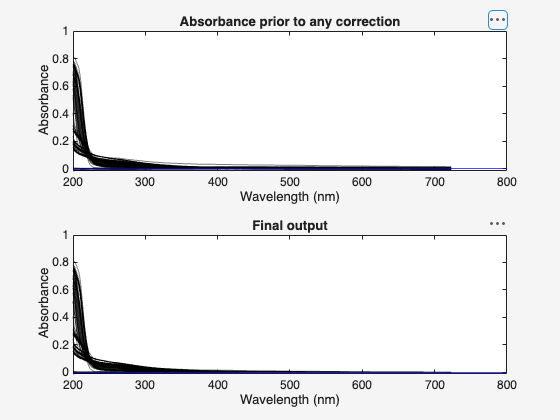

samples=tbx.mergemeasurements(samples,absorbance,"absorbance");
clearvars absorbance
samples=tbx.processabsorbance(samples);

That's job done for `absorbance`, we can delete it.

Our next task is to create a blank dataset that corresponds to the samples dataset. I.e. we make sure that the blank subtraction can be done with simple math $X_{\mathrm{blank}\;\mathrm{subtracted}} =X_{\mathrm{Sample}} -X_{\mathrm{Blank}}$. However, that's not how the dataset was collected. We have one blank per day. So we will have to replicate this blank for every sample EEM of the day.

blankNew=drEEMdataset;
for j=1:samples.nSample
    idx=matches(blanks.filelist,char(samples.metadata.blankFile(j)));
    idx=find(idx);
    if not(isempty(idx))
        blankNew.X(j,:,:)=blanks.X(idx,:,:);
        blankNew.filelist{j}=samples.filelist{j};
    else
        disp([char(samples.metadata.sampleFile(j)),'     ',])
    end
end
blankNew.nSample=size(blankNew.X,1);
blankNew.i=(1:blankNew.nSample)';
blankNew.metadata.i=blankNew.i;
blankNew.Ex=blanks.Ex;
blankNew.Em=blanks.Em;
blankNew.nEx=blanks.nEx;
blankNew.nEm=blanks.nEm;
blankNew.validate(blankNew);

This created a new dataset as we wanted. Next, we ensure that we have a blank for every sample and that both datasets are ordered the same.

[samples,blankNew] = tbx.alignsamples(samples,blankNew);

samples: No action necessary. All files between supplied datasets had same names.
blankNew: No action necessary. All files between supplied datasets had same names.


blanks=blankNew;
clearvars -except blanks samples tbx

That's it. Not simple, lot's of sources for errors, lot's of Matlab experience required. The easiest fix for this is to go with the recommendation at the top and store files as triplets with repeating tags.

## Basic processing

Just to demonstrate, we can now carry out the basic data processing with these datasets.

Abs-based IFE correction applied. 


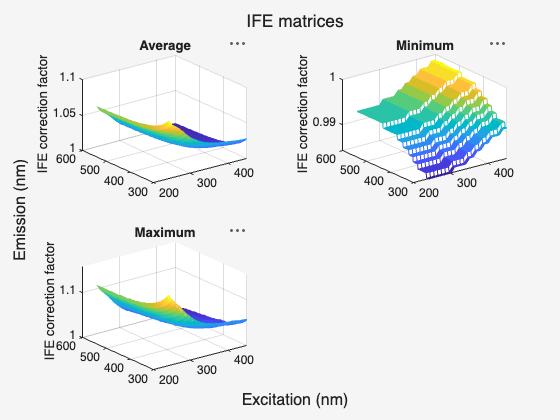

samples=tbx.ifecorrection(samples);

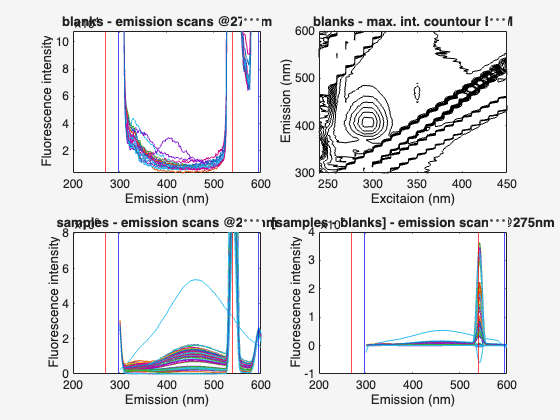

samples=tbx.subtractblanks(samples,blanks);

Raman normalization wavelength (350) found in EEM data.


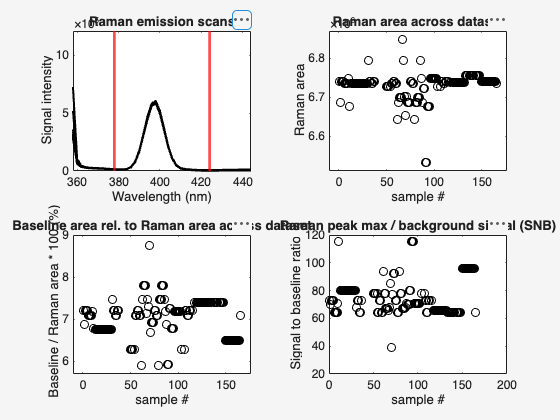

samples=tbx.ramancalibration(samples,blanks);


% tbx.viewscatter(samples)
load("scatteroptions.mat")
samples=tbx.handlescatter(samples,scatteroptions);

## Spectral correction

The toolbox comes with a function that can handle the spectral correction for you. The dataset loaded here is actually corrected, so I demonstrate this with a dummy vector for the correction spectra.

xcor=readmatrix("spectral_correction_factors.xlsx",Sheet="xcor");
mcor=readmatrix("spectral_correction_factors.xlsx",Sheet="mcor");
try
    samples=tbx.spectralcorrection(samples,"MCor",mcor,"XCor",xcor);
catch ME
    disp(ME.message)
end

Invalid argument at position 1. 
Spectral correction  is only possible if dataset status is "not applied".
Status is "applied by instrument software"



Trick (but I caught the error and displayed it instead of "throwing" the error)! I mentioned that the data comes spectrally corrected. The toolbox catches us trying to do something that's already done. In order to demonstrate the functionality, you'll have to change the status back to "`not applied`". I'll use an internal function to change the status programmatically so we can do a "dry-run" (dummy) spectral correction.

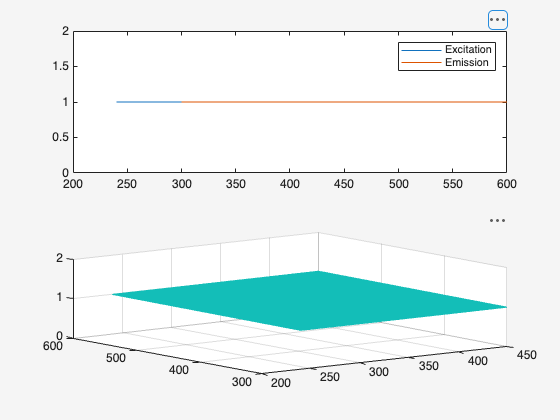

samples.status=drEEMstatus.change(samples.status,"spectralCorrection",'not applied');
samples=tbx.spectralcorrection(samples,"MCor",mcor,"XCor",xcor);

disp(samples.status.spectralCorrection)

applied by toolbox


cd ..
save('tutorial_02_importedAndProcessed.mat',"samples")
disp('Tutorial finished.')

Tutorial finished.
